# **FSIM (Functional SIMulator)**

**per ****f-HDGM**** e ****fp-HDGM**

Parametri da impostare:

- $\rho \ [1\times1]$;

- $\mathbf{c}_{\epsilon} \ [p_{\epsilon}\times 1]$;

- 
$$\mathbf{C}_{\beta} \ [b\times p_{\beta}]$$


- $\Sigma_0 \ [n\cdot p_z\times n\cdot p_z]$;

- $\mathbf{\mu}_0 \ [n\cdot p_z\times 1]$;

- $\mathbf{G} \ [p_z\times p_z]$;

- 
$$\mathbf{V} \ [p_z\times p_z]$$


- $\mathbf{\theta} \ [p_z\times 1]$;

- $n$, $q$, $b$ e $T$

addpath ..\'D-STEM v2.1'\Src\
clear all %#ok<CLALL> 
clc
rng('default')

exp_path = "..\Tesi\Immagini\";

#### **Scelta dei punti**

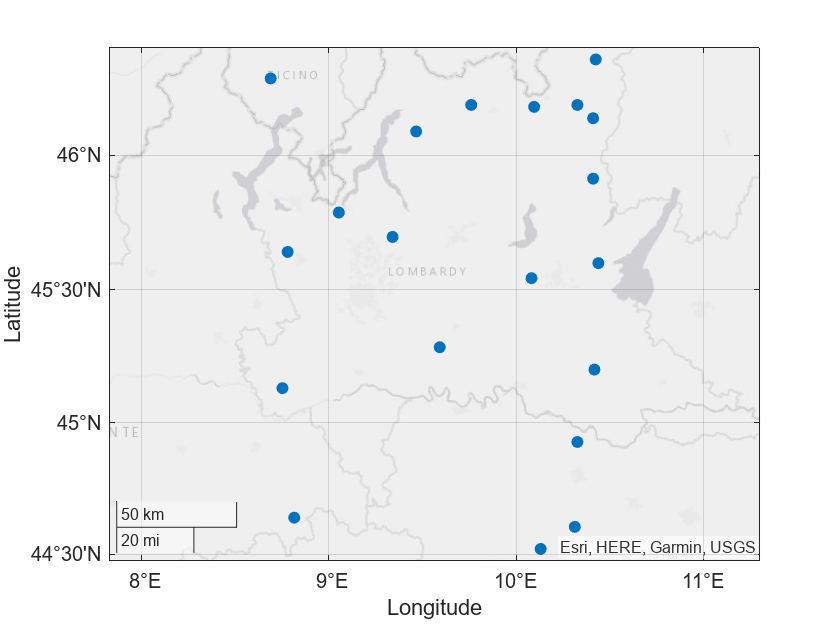

n = 20;
points = FSIM.get_points(n);

figure
geoscatter(points, "Latitude", "Longitude", "filled")

#### Visualizzazione delle spline

Scelta dei parametri

t_start = 0;
t_end = 23;
nbasis = 5;
exp_plot = true;

Visualizzazione delle singole funzioni base (coef. unitari)

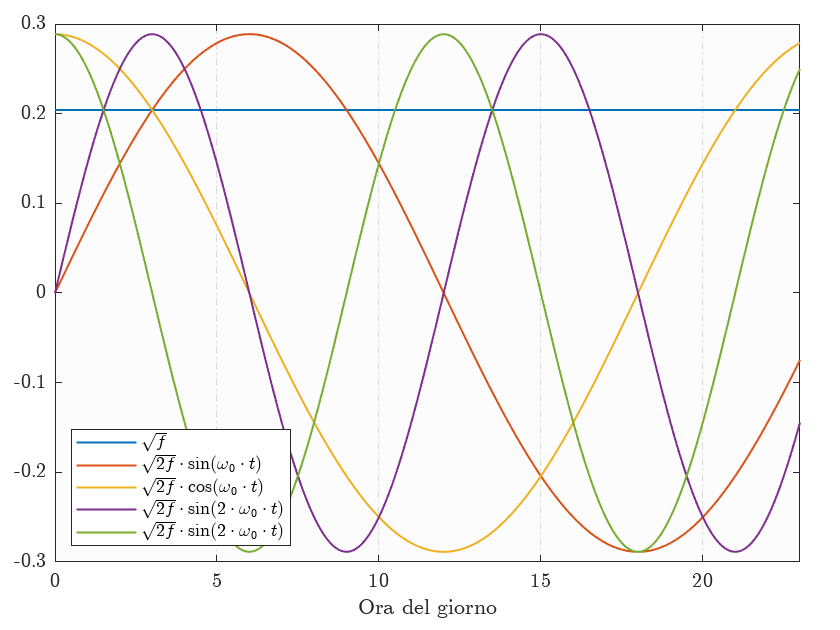

basis_obj = create_fourier_basis([0, t_end+1], nbasis);
t_domain = t_start:.1:t_end;
basis_eval = full(getbasismatrix(t_domain, basis_obj));

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
plot(t_domain, basis_eval(:, 1), 'LineWidth', 1)
hold on
for i=2:nbasis
    plot(t_domain, basis_eval(:, i), 'LineWidth', 1)
end
hold off

% configurazione degli assi
xlim([0 23])
axs = gca;
axs.XAxis.TickLabelInterpreter = 'latex';
xlabel("Ora del giorno", 'Interpreter', 'latex')
axs.YAxis.TickLabelInterpreter = 'latex';
legend(["$\sqrt{f}$", ...
        "$\sqrt{2f}\cdot\sin(\omega_0\cdot t)$", ...
        "$\sqrt{2f}\cdot\cos(\omega_0\cdot t)$", ...
        "$\sqrt{2f}\cdot\sin(2\cdot\omega_0\cdot t)$", ...
        "$\sqrt{2f}\cdot\sin(2\cdot\omega_0\cdot t)$"], ...
        'Location', 'southwest', 'Interpreter', 'latex')
grid on
axs.GridLineStyle = '-.';
axs.YGrid = "off";
axs.Color = [252/255, 252/255, 252/255];
if exp_plot
    exportgraphics(t, exp_path + "\Modello base\Basi Fourier.pdf");
end

Visualizzazione delle singole funzioni base (coef. non costanti)

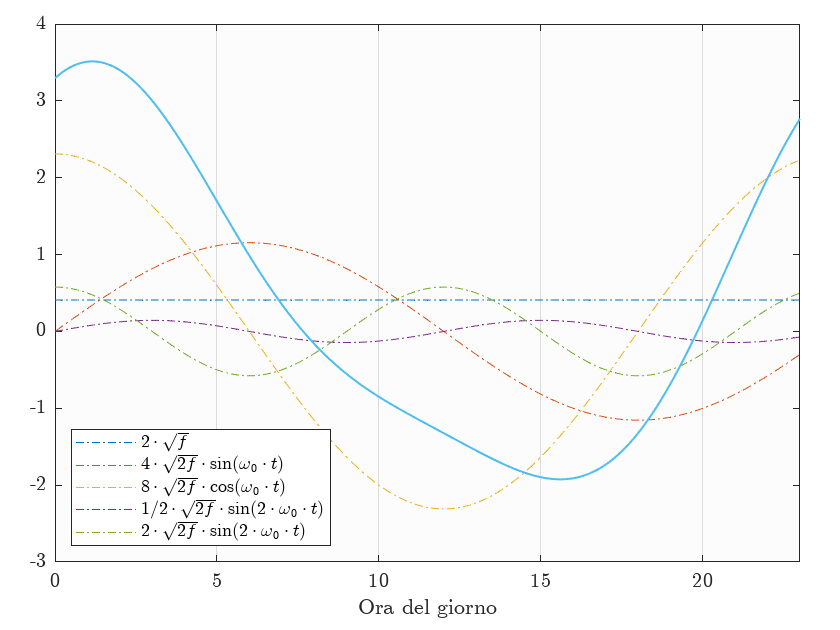

basis_eval_coef = repmat([2, 4, 8, .5, 2], size(t_domain, 2), 1).*basis_eval;

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
plot(t_domain, basis_eval_coef(:, 1), 'LineWidth', .5, 'LineStyle', '-.')
hold on
for i=2:nbasis
    plot(t_domain, basis_eval_coef(:, i), 'LineWidth', .5, 'LineStyle', '-.')
end
plot(t_domain, sum(basis_eval_coef(:, :), 2), 'LineWidth', 1)
hold off

% configurazione degli assi
xlim([0 23])
axs = gca;
axs.XAxis.TickLabelInterpreter = 'latex';
xlabel("Ora del giorno", 'Interpreter', 'latex')
axs.YAxis.TickLabelInterpreter = 'latex';
legend(["$2\cdot\sqrt{f}$", ...
        "$4\cdot\sqrt{2f}\cdot\sin(\omega_0\cdot t)$", ...
        "$8\cdot\sqrt{2f}\cdot\cos(\omega_0\cdot t)$", ...
        "$1/2\cdot\sqrt{2f}\cdot\sin(2\cdot\omega_0\cdot t)$", ...
        "$2\cdot\sqrt{2f}\cdot\sin(2\cdot\omega_0\cdot t)$"], ...
        'Location', 'southwest', 'Interpreter', 'latex')
grid on
axs.GridLineStyle = '-';
axs.YGrid = "off";
axs.Color = [252/255, 252/255, 252/255];
if exp_plot
    exportgraphics(t, exp_path + ...
        "\Modello base\Spline Fourier con coefficienti non unitari.pdf");
end

Confronto tra spline (coef. unitari)

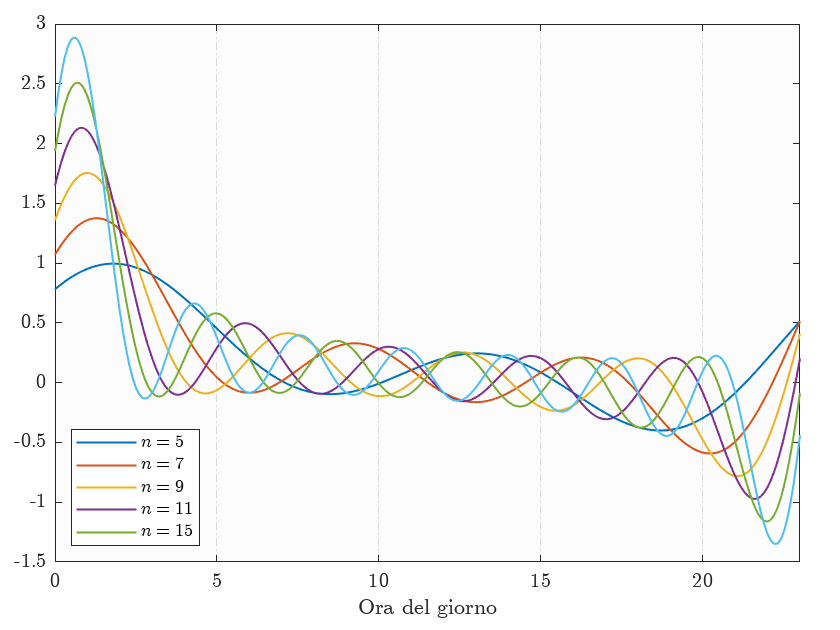

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
for i=5:2:15
    basis_obj = create_fourier_basis([0, t_end+1], i);
    basis_eval_2 = full(getbasismatrix(t_domain, basis_obj));
    plot(t_domain, sum(basis_eval_2(:, :), 2), 'LineWidth', 1)
    if i == 5
        hold on
    end
end
hold off

% configurazione degli assi
xlim([0 23])
axs = gca;
axs.XAxis.TickLabelInterpreter = 'latex';
xlabel("Ora del giorno", 'Interpreter', 'latex')
axs.YAxis.TickLabelInterpreter = 'latex';
legend(["$n = 5$", ...
        "$n = 7$", ...
        "$n = 9$", ...
        "$n = 11$", ...
        "$n = 15$"], ...
        'Location', 'southwest', 'Interpreter', 'latex')
grid on
axs.GridLineStyle = '-.';
axs.YGrid = "off";
axs.Color = [252/255, 252/255, 252/255];
if exp_plot
    exportgraphics(t, exp_path + "\Modello base\Spline Fourier.pdf");
end

#### Simulazione di un processo gaussiano

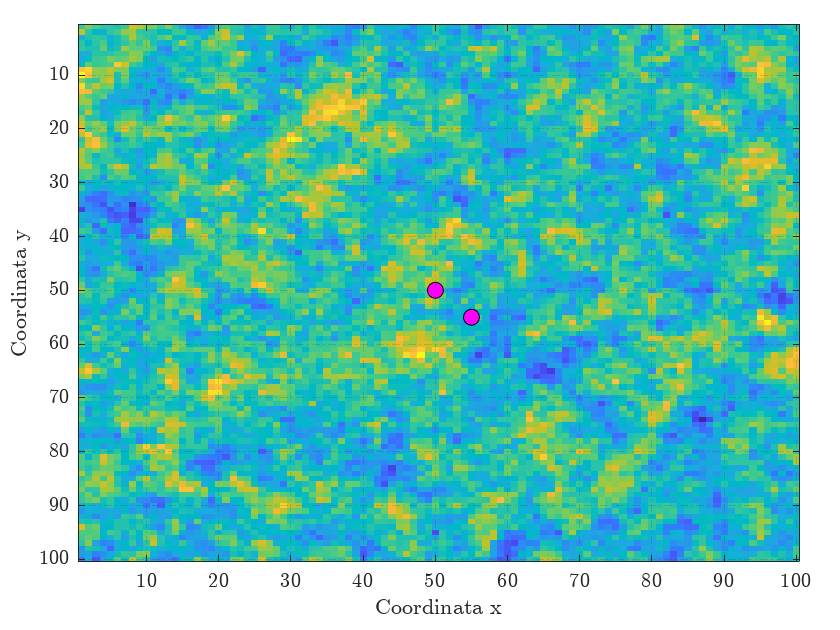

x = 0:1:99;
y = 0:1:99;
[X, Y] = meshgrid(x, y);
coord = [X(:) Y(:)];
x1 = 50;
x2 = 55;
x1_index = find(coord(:, 1) == x1 & coord(:, 2) == x1);
x2_index = find(coord(:, 1) == x2 & coord(:, 2) == x2);

theta = 2;
dist = pdist2(coord, coord, "euclidean");
sp_corr = exp(-dist/theta);

rng('default')
v = mvnrnd(zeros(1, size(dist,1)), sp_corr);
v = reshape(v, size(X));

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
imagesc(v)
hold on
plot(x1, x1, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'magenta', 'MarkerEdgeColor', 'black');
plot(x2, x2, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'magenta', 'MarkerEdgeColor', 'black');
hold off

% configurazione degli assi
xlabel("Coordinata x", 'Interpreter', 'latex');
ylabel("Coordinata y", 'Interpreter', 'latex');
axs = gca;
axs.XAxis.TickLabelInterpreter = 'latex';
axs.YAxis.TickLabelInterpreter = 'latex';
grid on
axs.GridLineStyle = '-.';
if exp_plot
    exportgraphics(t, exp_path + "\Modello base\Sim. proc. gaussiano, " + ...
        "theta = " + num2str(theta) + ".pdf");
end

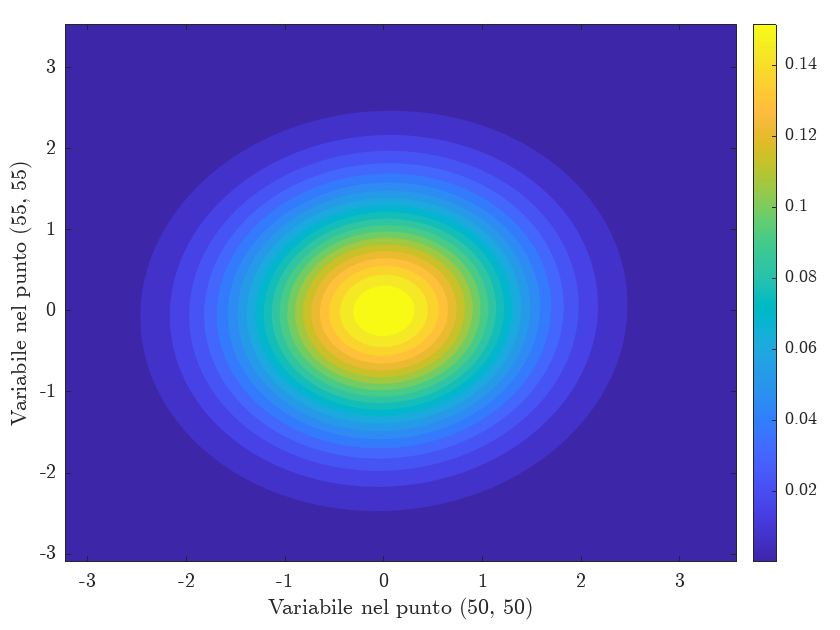

mu = [0 0];
sigma = [1 sp_corr(x1_index, x2_index); sp_corr(x1_index, x2_index) 1];

rng("default");
data = mvnrnd(mu, sigma, 1000);

x = linspace(min(data(:,1)), max(data(:,1)), 100);
y = linspace(min(data(:,2)), max(data(:,2)), 100);
[X, Y] = meshgrid(x, y);

Z = mvnpdf([X(:) Y(:)], mu, sigma);
Z = reshape(Z, size(X));

figure;
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
contourf(X, Y, Z, 20, 'LineColor', 'none');

% configurazione degli assi
xlabel("Variabile nel punto (" + num2str(x1) + ", " +  num2str(x1) + ")", 'Interpreter', 'latex');
ylabel("Variabile nel punto (" + num2str(x2) + ", " +  num2str(x2) + ")", 'Interpreter', 'latex');
axs = gca;
colorbar(axs, 'eastoutside', 'TickLabelInterpreter', 'latex');
axs.XAxis.TickLabelInterpreter = 'latex';
axs.YAxis.TickLabelInterpreter = 'latex';
if exp_plot
    exportgraphics(t, exp_path + "\Modello base\Sim. var. casuali, " + ...
        "theta = " + num2str(theta) + ".pdf");
end

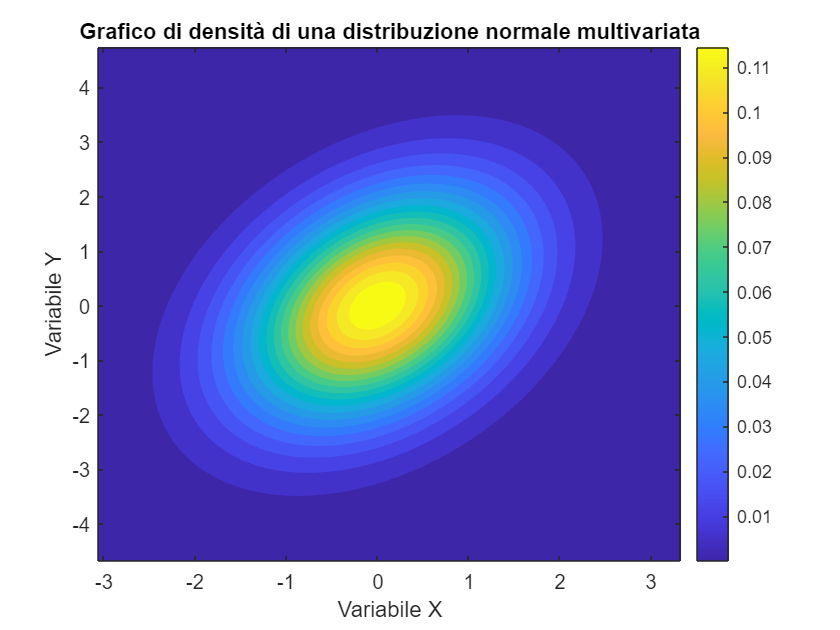

% Parametri della distribuzione normale multivariata
mu = [0 0];             % valor medio
sigma = [1 0.5; 0.5 2]; % matrice di covarianza

% Generazione di dati casuali da una distribuzione normale multivariata
rng(1);  % Impostazione del seed per riproducibilità
data = mvnrnd(mu, sigma, 1000);

% Creazione di una griglia per il grafico di densità
x = linspace(min(data(:,1)), max(data(:,1)), 100);
y = linspace(min(data(:,2)), max(data(:,2)), 100);
[X, Y] = meshgrid(x, y);

% Calcolo della densità di probabilità sulla griglia
Z = mvnpdf([X(:) Y(:)], mu, sigma);
Z = reshape(Z, size(X));

% Generazione del grafico di densità
figure;
contourf(X, Y, Z, 20, 'LineColor', 'none');
colorbar;
title('Grafico di densità di una distribuzione normale multivariata');
xlabel('Variabile X');
ylabel('Variabile Y');

#### Impostazione dei parametri

rng('default')

q = 24;
T = 50;
params.rho = .4;
params.theta = [.4; .4; .4; .4; .4; .4; .4];
n_basis.p_eps = 5;
n_basis.p_beta = 7;
n_basis.p_z = 7;

b = 2;
X = cell(T, 1);
for t=1:T
    X_t = ones(q*n, 2);
    for i=2:b
        X_t(:, 2) = randi(100, q*n, 1);
    end
    X{t} = X_t;
end

obj = FSIM(points, q, T, "NumBasis", n_basis, "Parameters", params);

FSIM (Functional SIMulator)
 
Authors: 
- Lorenzo LEONI
- Nicola ZAMBELLI
 
Dimensions: 
- n, q, b and T: [20 24 1 50]
- p_eps, p_beta and p_z: [5 7 7]
 
Parameters set: 
- rho: 0.4
- c_eps: [23      1.34285   -0.0643863     0.626866     0.446795]
- c_beta_1: [45  61  71  24  46   5  62]
- diag_G: [0.039692     0.53707     0.19161     0.16365     0.69724     0.66872     0.78439]
- diag_V: [6  8  6  6  4  6  5]
- theta: [0.4         0.4         0.4         0.4         0.4         0.4         0.4]


#### Avvio della/e simulazione/i

rng('default')
obj = obj.run(10);

Running simulation/s: 
- sim. 1 of 10 done.
- sim. 2 of 10 done.
- sim. 3 of 10 done.
- sim. 4 of 10 done.
- sim. 5 of 10 done.
- sim. 6 of 10 done.
- sim. 7 of 10 done.
- sim. 8 of 10 done.
- sim. 9 of 10 done.
- sim. 10 of 10 done.


**NB**: si ricorda che le osservazioni $Y_{sim}$ sono impilate prima per $q$, poi per $n$ (fissato $q$, viene espresso il valore di $y$ assunto presso le diverse $n$ stazioni).

#### Formattazione dei dati per rispettare la sintassi di D-STEM

data = obj.format_data;

Running data formatting: 
- dataset 1 of 10 done.
- dataset 2 of 10 done.
- dataset 3 of 10 done.
- dataset 4 of 10 done.
- dataset 5 of 10 done.
- dataset 6 of 10 done.
- dataset 7 of 10 done.
- dataset 8 of 10 done.
- dataset 9 of 10 done.
- dataset 10 of 10 done.


#### Validazione dei modelli spazio-temporali

Model type definition

o_modeltype = stem_modeltype('f-HDGM');
if obj.params.rho == 0
    o_modeltype.flag_potential = false;
else
    o_modeltype.flag_potential = true;
end

Basis configuration

input_fda.spline_type = 'Fourier';
input_fda.spline_range = [0 q];
input_fda.spline_nbasis_z = n_basis.p_z;
input_fda.spline_nbasis_beta = n_basis.p_beta; 
input_fda.spline_nbasis_sigma = n_basis.p_eps;
o_fda = stem_fda(input_fda);

Input data

input_data.stem_modeltype = o_modeltype;
input_data.data_table = data{1};
input_data.stem_fda = o_fda;
o_data = stem_data(input_data);

 
**********************************************
*   Data description of stem_varset object   *
**********************************************
Maximum number of observations per profile: q=24
 
Number of spatial locations: n=20
 
Number of time steps: T=50
 
Generating data matrices...
Generation ended.
Looking for duplicated sites...
Operation ended.


Input parameters

o_par = stem_par(o_data, 'exponential');

if obj.params.rho ~= 0
    o_par.rho = 2; %obj.params.rho;
end
o_model = stem_model(o_data, o_par);

Generating data matrices...
Generation ended.


% if model is fp-HDGM, then from the observed data is removed
% the conditional component thanks to diag_H_inv before the parameters
% initialization
if o_modeltype.is('f-HDGM') && o_modeltype.flag_potential
    
    % input parameters
    T = size(o_model.stem_data.Y, 2);
    n = size(o_model.stem_data.stem_gridlist_p.grid{1, 1}.coordinate, 1);
    q = o_model.stem_par.q;
    o_model.set_distance_matrix
    Y = o_model.stem_data.Y;
    
    % computation of diag_H_inv
    diag_H_inv = stem_misc.compute_H_inv(o_model.DistMat_rho, ...
        q, o_model.stem_par.rho);
    
    % update of Y
    Y_pot = zeros(size(o_model.stem_data.Y));
    for t=1:T
        Y_pot(:, t) = diag_H_inv.*Y(:, t);
    end
    o_model.stem_data.stem_varset_p.Y = mat2cell(Y_pot, n.*ones(1, q));
    o_model.stem_data.Y = Y_pot;
 
end

Generating point distance matrices...
Generation ended.


n_basis = o_fda.get_basis_number;

o_par.beta = obj.params.c_beta;
o_par.sigma_eps = obj.params.c_eps;
o_par.theta_z = obj.params.theta';
o_par.G = diag(obj.params.diag_G);
o_par.v_z = diag(obj.params.diag_V);

o_model.set_initial_values(o_par);

o_model.stem_data.stem_varset_p.Y = mat2cell(Y, n.*ones(1, q));
o_model.stem_data.Y = Y;

Model estimation

% EM parameters
o_EM_options = stem_EM_options();
o_EM_options.exit_tol_par = 0.0001; 
o_EM_options.exit_tol_loglike = 0.0001; 
o_EM_options.max_iterations = 100;

% EM estimation
o_model.EM_estimate(o_EM_options);

Generating point distance matrices...
Generation ended.
 
**********************
*   D-STEM version   *
**********************
 
Model estimation is performed using D-STEM v2
 
******************************
*   Brief data description   *
******************************
Number of variables: q=24
 
Point variables:
sum of points for each variable: Nq=480
sum of sites for each variable: N=20
 
Date and time steps:
  Stating date  : 01-Jan-2023
  Ending date   : 19-Feb-2023
  Temporal steps: 50
 
Bounding box of the point data:
  Latitude min : 44.52 deg
  Latitude max : 46.35 deg
  Longitude min: 08.69 deg
  Longitude max: 10.44 deg
 
Number of latent variables: p=7
 
Covariates related to beta:
    {'const'}

************************
Iteration 1 started...
************************
  E step started...
    Kalman smoother started...
    Kalman smoother ended in 1.04s
    Xbeta evaluation started...
    Xbeta evaluation ended in 0.00s
    Conditional E, Var, Cov evaluation started...
    Co

    G updating ended in 0.04s
    v_z and theta_z updating started...
    v_z updating ended in 0.02s
    theta_z updating ended in 0.05s
  M step ended in 0.62s
****************
logL: -463215.6535
logL relative delta: 1
Parameter delta norm: 50.0589
****************
PARAMETER VALUES
****************
beta: 138.8984      139.9269      208.8698      73.03566      92.60131      25.04973       97.8883
sigma_eps: 39.0682      2.43189      2.45644      1.46885      1.71946
diag_G: 0.039692     0.53707     0.19161     0.16365     0.69724     0.66872     0.78439
theta_z: 1.1698      1.9953      1.7448     0.68544      1.9779     0.43897      1.9948
rho: 0.75504
v_z: 
   63.0120         0         0         0         0         0         0
         0  347.1056         0         0         0         0         0
         0         0  225.2654         0         0         0         0
         0         0         0   17.8634         0         0         0
         0         0         0         0  137.92

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.24s
****************
logL: -58051.8909
logL relative delta: 0.052683
Parameter delta norm: 0.1969
****************
PARAMETER VALUES
****************
beta: 79.83954      110.8768      150.6758      29.81319      72.19172      5.442078      99.81452
sigma_eps: 18.1377      1.30516     -0.13687     0.571718     0.514034
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 3.805      7.7415      7.6171      1.3727      5.4662      0.5565      6.7417
rho: 0.2169
v_z: 
   28.5952         0         0         0         0         0         0
         0   73.6306         0         0         0         0         0
         0         0   83.7302         0         0         0         0
         0         0         0   10.4256         0         0         0
         0         0         0         0   41.

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.25s
****************
logL: -55032.7748
logL relative delta: 0.05486
Parameter delta norm: 0.19134
****************
PARAMETER VALUES
****************
beta: 79.71722      110.8014      150.5705      29.71322      72.09614      5.186554      99.78627
sigma_eps: 16.875      1.30573    -0.137298     0.569708     0.513834
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 4.5058      9.1639      9.0746      1.5949      6.3536     0.58925      7.8702
rho: 0.18662
v_z: 
   26.8408         0         0         0         0         0         0
         0   65.7150         0         0         0         0         0
         0         0   80.6709         0         0         0         0
         0         0         0    9.1389         0         0         0
         0         0         0         0   37

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.24s
****************
logL: -52070.7632
logL relative delta: 0.056884
Parameter delta norm: 0.18446
****************
PARAMETER VALUES
****************
beta: 79.61238      110.7364      150.4819      29.62213      72.01264      4.971343      99.76202
sigma_eps: 15.632      1.30669    -0.137298     0.566203     0.513884
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 5.30995      10.7602      10.7486      1.85062      7.34173     0.630335      9.12128
rho: 0.15777
v_z: 
   25.7395         0         0         0         0         0         0
         0   60.2714         0         0         0         0         0
         0         0   79.3121         0         0         0         0
         0         0         0    8.1115         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.02s
    theta_z updating ended in 0.04s
  M step ended in 0.37s
****************
logL: -49186.7401
logL relative delta: 0.058634
Parameter delta norm: 0.1768
****************
PARAMETER VALUES
****************
beta: 79.52437      110.6815      150.4085      29.54097      71.94066      4.791199      99.74182
sigma_eps: 14.4195      1.30854     -0.13644     0.561116     0.514436
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 6.21878      12.5189      12.6489      2.13974      8.42101     0.680957      10.4863
rho: 0.12988
v_z: 
   25.1683         0         0         0         0         0         0
         0   56.7392         0         0         0         0         0
         0         0   79.2514         0         0         0         0
         0         0         0    7.3066         0         0         0
         0         0         0       

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.17s
****************
logL: -46424.9659
logL relative delta: 0.059489
Parameter delta norm: 0.16882
****************
PARAMETER VALUES
****************
beta: 79.45172       110.636      150.3483      29.46986      71.87929      4.640899      99.72541
sigma_eps: 13.2588      1.31154    -0.133935     0.554596     0.515742
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 7.23105      14.4242      14.7843      2.45953       9.5766     0.741671      11.9587
rho: 0.10272
v_z: 
   25.0222         0         0         0         0         0         0
         0   54.6815         0         0         0         0         0
         0         0   80.1673         0         0         0         0
         0         0         0    6.6919         0         0         0
         0         0         0      

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.18s
****************
logL: -43881.1075
logL relative delta: 0.057972
Parameter delta norm: 0.16038
****************
PARAMETER VALUES
****************
beta: 79.39232      110.5985      150.2992      29.40827      71.82731      4.515375      99.71229
sigma_eps: 12.1944      1.31641    -0.129174     0.547013     0.518009
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 8.34161      16.4512      17.1555      2.80341      10.7878     0.811427       13.531
rho: 0.076141
v_z: 
   25.2154         0         0         0         0         0         0
         0   53.7674         0         0         0         0         0
         0         0   81.8326         0         0         0         0
         0         0         0    6.2394         0         0         0
         0         0         0     

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.17s
****************
logL: -41718.453
logL relative delta: 0.051839
Parameter delta norm: 0.15015
****************
PARAMETER VALUES
****************
beta: 79.34369      110.5677      150.2588      29.35511       71.7832      4.409592      99.70182
sigma_eps: 11.2977      1.32329    -0.121706     0.539321     0.521398
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 9.53307      18.5547      19.7315      3.16114      12.0237     0.886713      15.1856
rho: 0.05008
v_z: 
   25.6856         0         0         0         0         0         0
         0   53.7696         0         0         0         0         0
         0         0   84.1418         0         0         0         0
         0         0         0    5.9244         0         0         0
         0         0         0       

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.20s
****************
logL: -40173.8928
logL relative delta: 0.038447
Parameter delta norm: 0.13655
****************
PARAMETER VALUES
****************
beta: 79.30316      110.5419      150.2249      29.30876      71.74519      4.318631      99.69329
sigma_eps: 10.6658      1.33162    -0.112673     0.533317     0.526082
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 10.7711      20.6553      22.4258      3.51794      13.2367     0.960775      16.8736
rho: 0.026839
v_z: 
   26.3934         0         0         0         0         0         0
         0   54.5499         0         0         0         0         0
         0         0   87.1100         0         0         0         0
         0         0         0    5.7240         0         0         0
         0         0         0     

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.32s
****************
logL: -39481.8065
logL relative delta: 0.017529
Parameter delta norm: 0.11936
****************
PARAMETER VALUES
****************
beta: 79.26812      110.5194      150.1953      29.26722      71.71138      4.237778      99.68604
sigma_eps: 10.3855       1.3391    -0.106776     0.530973     0.531425
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 12.005      22.6532      25.1026      3.85839      14.3684        1.025      18.5002
rho: 0.0017797
v_z: 
   27.3002         0         0         0         0         0         0
         0   55.9804         0         0         0         0         0
         0         0   90.7540         0         0         0         0
         0         0         0    5.6147         0         0         0
         0         0         0     

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.22s
****************
logL: -39349.1539
logL relative delta: 0.0033712
Parameter delta norm: 0.10666
****************
PARAMETER VALUES
****************
beta: 79.23598      110.4987       150.168      29.22804      71.67962       4.16177      99.67951
sigma_eps: 10.3325      1.34243    -0.105274     0.530869     0.534383
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 13.2369      24.5752      27.7801       4.1835      15.4395      1.07782      20.0595
rho: 0.0017797
v_z: 
   28.2827         0         0         0         0         0         0
         0   57.7269         0         0         0         0         0
         0         0   94.6497         0         0         0         0
         0         0         0    5.5597         0         0         0
         0         0         0   

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.17s
****************
logL: -39325.5357
logL relative delta: 0.00060058
Parameter delta norm: 0.10059
****************
PARAMETER VALUES
****************
beta: 79.20524      110.4789      150.1416       29.1897      71.64864      4.087305      99.67336
sigma_eps: 10.3337      1.34276    -0.104616     0.530921     0.535114
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 14.5062      26.5131      30.5746      4.50389      16.5119      1.12284      21.6211
rho: 0.0017797
v_z: 
   29.2287         0         0         0         0         0         0
         0   59.4976         0         0         0         0         0
         0         0   98.3560         0         0         0         0
         0         0         0    5.5292         0         0         0
         0         0         0  

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.25s
****************
logL: -39305.616
logL relative delta: 0.00050679
Parameter delta norm: 0.096201
****************
PARAMETER VALUES
****************
beta: 79.17546      110.4597      150.1159      29.15183      71.61814      4.013666      99.66749
sigma_eps: 10.3391      1.34224    -0.103799     0.530818      0.53548
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 15.8244      28.4907      33.5159      4.82244      17.6022      1.16172      23.2031
rho: 0.0017797
v_z: 
   30.1215         0         0         0         0         0         0
         0   61.2320         0         0         0         0         0
         0         0  101.8246         0         0         0         0
         0         0         0    5.5141         0         0         0
         0         0         0  

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 0.27s
****************
logL: -39287.9408
logL relative delta: 0.00044989
Parameter delta norm: 0.092145
****************
PARAMETER VALUES
****************
beta: 79.14653       110.441      150.0907      29.11442       71.5881      3.940852      99.66186
sigma_eps: 10.3446      1.34165    -0.102988     0.530714     0.535846
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 17.1903      30.5066      36.6042      5.13875      18.7105      1.19518      24.8075
rho: 0.0017797
v_z: 
   30.9709         0         0         0         0         0         0
         0   62.9303         0         0         0         0         0
         0         0  105.1024         0         0         0         0
         0         0         0    5.5116         0         0         0
         0         0         0 

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.16s
****************
logL: -39272.1196
logL relative delta: 0.00040286
Parameter delta norm: 0.088232
****************
PARAMETER VALUES
****************
beta: 79.11837      110.4228      150.0661      29.07745      71.55852      3.868922      99.65646
sigma_eps: 10.3497      1.34106    -0.102183     0.530662      0.53616
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 18.6013      32.5583      39.8339      5.45184      19.8362      1.22365      26.4319
rho: 0.0017797
v_z: 
   31.7861         0         0         0         0         0         0
         0   64.5971         0         0         0         0         0
         0         0  108.2313         0         0         0         0
         0         0         0    5.5198         0         0         0
         0         0         0 

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.23s
****************
logL: -39257.8652
logL relative delta: 0.0003631
Parameter delta norm: 0.084526
****************
PARAMETER VALUES
****************
beta: 79.09089       110.405       150.042      29.04093      71.52939      3.797927      99.65128
sigma_eps: 10.3544       1.3406    -0.101465     0.530558     0.536526
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 20.0559      34.6404      43.2009      5.76144      20.9775      1.24762      28.0742
rho: 0.0017797
v_z: 
   32.5743         0         0         0         0         0         0
         0   66.2359         0         0         0         0         0
         0         0  111.2428         0         0         0         0
         0         0         0    5.5370         0         0         0
         0         0         0  

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.26s
****************
logL: -39244.9485
logL relative delta: 0.00032913
Parameter delta norm: 0.080986
****************
PARAMETER VALUES
****************
beta: 79.06406      110.3877      150.0184      29.00486      71.50072      3.727917      99.64628
sigma_eps: 10.3588      1.34014    -0.100751     0.530507     0.536893
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 21.5508      36.7498      46.6995      6.06682      22.1336      1.26739      29.7303
rho: 0.0017797
v_z: 
   33.3408         0         0         0         0         0         0
         0   67.8495         0         0         0         0         0
         0         0  114.1608         0         0         0         0
         0         0         0    5.5619         0         0         0
         0         0         0 

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.20s
****************
logL: -39233.1922
logL relative delta: 0.00029965
Parameter delta norm: 0.07776
****************
PARAMETER VALUES
****************
beta: 79.03782      110.3707      149.9953      28.96926      71.47249      3.658932      99.64146
sigma_eps: 10.3629      1.33975    -0.100122     0.530455      0.53726
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 23.0842      38.8856      50.3309      6.36721      23.3031      1.28345      31.4006
rho: 0.0017797
v_z: 
   34.0899         0         0         0         0         0         0
         0   69.4398         0         0         0         0         0
         0         0  117.0033         0         0         0         0
         0         0         0    5.5933         0         0         0
         0         0         0  

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.20s
****************
logL: -39222.4421
logL relative delta: 0.00027408
Parameter delta norm: 0.074595
****************
PARAMETER VALUES
****************
beta: 79.01215      110.3542      149.9725       28.9341      71.44471      3.591011       99.6368
sigma_eps: 10.3667      1.33936   -0.0994959     0.530403     0.537627
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 24.6532      41.0423      54.0853      6.66278      24.4858      1.29602      33.0796
rho: 0.0017797
v_z: 
   34.8247         0         0         0         0         0         0
         0   71.0086         0         0         0         0         0
         0         0  119.7846         0         0         0         0
         0         0         0    5.6302         0         0         0
         0         0         0 

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.05s
  M step ended in 0.32s
****************
logL: -39212.5816
logL relative delta: 0.00025146
Parameter delta norm: 0.071621
****************
PARAMETER VALUES
****************
beta: 78.98699      110.3379      149.9502      28.89941      71.41737      3.524184      99.63229
sigma_eps: 10.3702      1.33903   -0.0988741     0.530403     0.537995
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 26.256      43.2158       57.959      6.95274      25.6802      1.30538      34.7687
rho: 0.0017797
v_z: 
   35.5476         0         0         0         0         0         0
         0   72.5570         0         0         0         0         0
         0         0  122.5152         0         0         0         0
         0         0         0    5.6718         0         0         0
         0         0         0  

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.20s
****************
logL: -39203.508
logL relative delta: 0.00023145
Parameter delta norm: 0.068767
****************
PARAMETER VALUES
****************
beta: 78.96234      110.3221      149.9283      28.86517      71.39047      3.458474      99.62792
sigma_eps: 10.3736       1.3387   -0.0982561     0.530351     0.538363
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 27.8884      45.4074      61.9447      7.23754      26.8837      1.31185      36.4624
rho: 0.0017797
v_z: 
   36.2605         0         0         0         0         0         0
         0   74.0857         0         0         0         0         0
         0         0  125.2034         0         0         0         0
         0         0         0    5.7173         0         0         0
         0         0         0  

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.19s
****************
logL: -39195.1361
logL relative delta: 0.0002136
Parameter delta norm: 0.066113
****************
PARAMETER VALUES
****************
beta: 78.93816      110.3065      149.9068      28.83138        71.364      3.393903      99.62368
sigma_eps: 10.3767      1.33844   -0.0977188     0.530351     0.538678
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 29.5494      47.6123        66.04      7.51699      28.0963      1.31568      38.1624
rho: 0.0017797
v_z: 
   36.9647         0         0         0         0         0         0
         0   75.5956         0         0         0         0         0
         0         0  127.8554         0         0         0         0
         0         0         0    5.7659         0         0         0
         0         0         0  

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.20s
****************
logL: -39187.3896
logL relative delta: 0.00019768
Parameter delta norm: 0.063576
****************
PARAMETER VALUES
****************
beta: 78.91443      110.2913      149.8857      28.79803      71.33795       3.33049      99.61955
sigma_eps: 10.3796      1.33818   -0.0972607     0.530299     0.539046
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 31.2348      49.8267      70.2385      7.79061      29.3165      1.31709      39.8653
rho: 0.0017797
v_z: 
   37.6614         0         0         0         0         0         0
         0   77.0872         0         0         0         0         0
         0         0  130.4767         0         0         0         0
         0         0         0    5.8172         0         0         0
         0         0         0 

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.30s
****************
logL: -39180.2089
logL relative delta: 0.00018327
Parameter delta norm: 0.061175
****************
PARAMETER VALUES
****************
beta: 78.89113      110.2763      149.8649      28.76512      71.31233      3.268249      99.61554
sigma_eps: 10.3823      1.33792   -0.0967288     0.530299     0.539362
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 32.9438      52.0476      74.5354      8.05828      30.5406      1.31631      41.5686
rho: 0.0017797
v_z: 
   38.3513         0         0         0         0         0         0
         0   78.5610         0         0         0         0         0
         0         0  133.0713         0         0         0         0
         0         0         0    5.8707         0         0         0
         0         0         0 

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.28s
****************
logL: -39173.5394
logL relative delta: 0.00017025
Parameter delta norm: 0.058874
****************
PARAMETER VALUES
****************
beta: 78.86824      110.2616      149.8445      28.73263      71.28712      3.207195      99.61163
sigma_eps: 10.3849      1.33772   -0.0962754     0.530299     0.539678
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 34.6742      54.2734      78.9236      8.32026      31.7705      1.31356      43.2707
rho: 0.0017797
v_z: 
   39.0351         0         0         0         0         0         0
         0   80.0171         0         0         0         0         0
         0         0  135.6424         0         0         0         0
         0         0         0    5.9258         0         0         0
         0         0         0 

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.20s
****************
logL: -39167.3316
logL relative delta: 0.00015849
Parameter delta norm: 0.056688
****************
PARAMETER VALUES
****************
beta: 78.84574      110.2473      149.8245      28.70057      71.26233      3.147338      99.60781
sigma_eps: 10.3873      1.33753   -0.0958241     0.530299     0.539942
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 36.4219      56.5037      83.3976      8.57632      33.0037      1.30902      44.9709
rho: 0.0017797
v_z: 
   39.7133         0         0         0         0         0         0
         0   81.4556         0         0         0         0         0
         0         0  138.1928         0         0         0         0
         0         0         0    5.9823         0         0         0
         0         0         0 

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.18s
****************
logL: -39161.5447
logL relative delta: 0.00014777
Parameter delta norm: 0.054572
****************
PARAMETER VALUES
****************
beta: 78.82363      110.2331      149.8047      28.66891      71.23795      3.088688      99.60409
sigma_eps: 10.3896      1.33733   -0.0954498     0.530299     0.540258
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 38.1864      58.7338      87.9488      8.82648      34.2406       1.3029      46.6695
rho: 0.0017797
v_z: 
   40.3862         0         0         0         0         0         0
         0   82.8768         0         0         0         0         0
         0         0  140.7243         0         0         0         0
         0         0         0    6.0396         0         0         0
         0         0         0 

    G updating ended in 0.00s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.17s
****************
logL: -39156.1408
logL relative delta: 0.00013801
Parameter delta norm: 0.052539
****************
PARAMETER VALUES
****************
beta: 78.80187      110.2193      149.7854      28.63765      71.21398      3.031254      99.60045
sigma_eps: 10.3916      1.33713   -0.0950769     0.530248     0.540522
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 39.9652      60.9592      92.5696      9.07102      35.4764      1.29532      48.3589
rho: 0.0017797
v_z: 
   41.0541         0         0         0         0         0         0
         0   84.2809         0         0         0         0         0
         0         0  143.2382         0         0         0         0
         0         0         0    6.0976         0         0         0
         0         0         0 

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.18s
****************
logL: -39151.0904
logL relative delta: 0.000129
Parameter delta norm: 0.050655
****************
PARAMETER VALUES
****************
beta: 78.78047      110.2057      149.7663      28.60678       71.1904      2.975044      99.59688
sigma_eps: 10.3937      1.33694   -0.0947056     0.530248     0.540786
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 41.7529      63.1826      97.2587      9.30998      36.7122      1.28638      50.0454
rho: 0.0017797
v_z: 
   41.7173         0         0         0         0         0         0
         0   85.6676         0         0         0         0         0
         0         0  145.7357         0         0         0         0
         0         0         0    6.1560         0         0         0
         0         0         0   

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.30s
****************
logL: -39146.3614
logL relative delta: 0.0001208
Parameter delta norm: 0.048816
****************
PARAMETER VALUES
****************
beta: 78.7594      110.1923      149.7476      28.57628      71.16722      2.920063       99.5934
sigma_eps: 10.3956      1.33681   -0.0943356     0.530248      0.54105
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 43.55183      65.40149      102.0065      9.543602      37.94683      1.276296      51.72225
rho: 0.0017797
v_z: 
   42.3756         0         0         0         0         0         0
         0   87.0372         0         0         0         0         0
         0         0  148.2175         0         0         0         0
         0         0         0    6.2146         0         0         0
         0         0      

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.19s
****************
logL: -39141.9275
logL relative delta: 0.00011328
Parameter delta norm: 0.047088
****************
PARAMETER VALUES
****************
beta: 78.73866      110.1792      149.7291      28.54615      71.14444      2.866316      99.58998
sigma_eps: 10.3974      1.33668   -0.0939671     0.530299     0.541261
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 45.3579      67.61419      106.8098      9.771237      39.18262      1.265155      53.39295
rho: 0.0017797
v_z: 
   43.0292         0         0         0         0         0         0
         0   88.3897         0         0         0         0         0
         0         0  150.6841         0         0         0         0
         0         0         0    6.2731         0         0         0
         0         0     

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.18s
****************
logL: -39137.7653
logL relative delta: 0.00010635
Parameter delta norm: 0.04542
****************
PARAMETER VALUES
****************
beta: 78.71823      110.1663       149.711      28.51637      71.12204      2.813808      99.58664
sigma_eps: 10.3991      1.33648   -0.0936735     0.530299     0.541526
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 47.1672      69.81964      111.6611      9.993966      40.41214      1.253125      55.05148
rho: 0.0017797
v_z: 
   43.6781         0         0         0         0         0         0
         0   89.7253         0         0         0         0         0
         0         0  153.1362         0         0         0         0
         0         0         0    6.3314         0         0         0
         0         0      

    G updating ended in 0.01s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.19s
****************
logL: -39133.8553
logL relative delta: 9.9914e-05
Parameter delta norm: 0.043816
****************
PARAMETER VALUES
****************
beta: 78.6981      110.1536      149.6932      28.48693      71.10003      2.762546      99.58335
sigma_eps: 10.4007      1.33635   -0.0933076     0.530299     0.541737
diag_G: 0.99932     0.99858     0.99992     0.98359     0.99685     0.66959      0.9969
theta_z: 48.98071      72.01381      116.5537      10.21142      41.63841      1.240268      56.69715
rho: 0.0017797
v_z: 
   44.3223         0         0         0         0         0         0
         0   91.0442         0         0         0         0         0
         0         0  155.5738         0         0         0         0
         0         0         0    6.3893         0         0         0
         0         0     